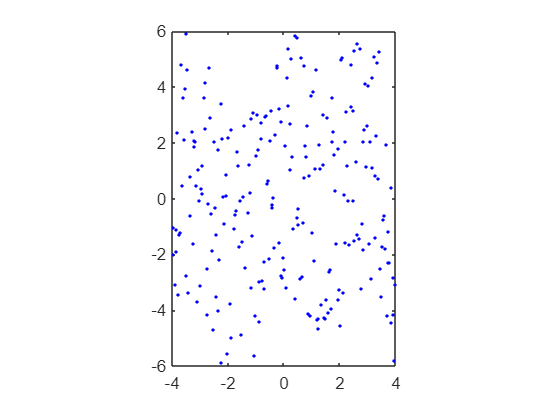

N = 300;
f = @(x) sin(x) + cos(2*x);
xmin = -5; xmax = 5;
ymin = -6; ymax = 6;
delta = (xmax - xmin)/N;
xs = linspace(xmin, xmax, N)' + (rand([N 1]) - 0.5)*delta;
ys = f(xs) + (rand([N 1]) - 0.5)*10;
fig1 = figure(1);
plot(xs, ys, '.b')
hold on;
%plot(xs, f(xs), '-g');
axis([xmin + 1 xmax - 1 ymin ymax]);
daspect([1 1 1]);
hold off

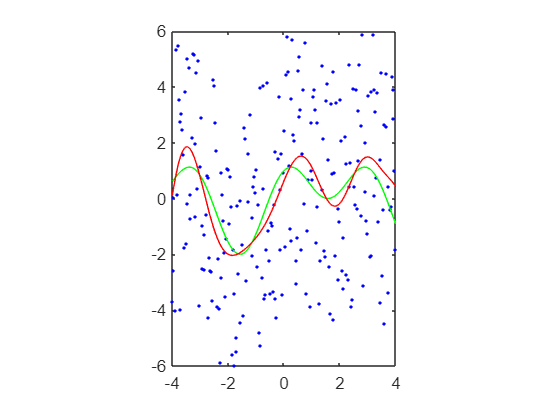

M = 17;
A = fliplr(vander(xs));
A = A(:,1:M);
xhat = (A'*A)^-1*A'*ys;
yhat  = A*xhat;
fig2 = figure(2);
plot(xs, ys, '.b')
hold on;
plot(xs, f(xs), '-g');
plot(xs, yhat, "-r");
axis([xmin + 1 xmax - 1 ymin ymax]);
daspect([1 1 1]);
hold off

How about a more interesting set of basis functions, let's use $\{1, x, x^2, \sin(x), \cos(x), \sin(2 x),\cos(2x)\}$ as the set of basis functions..

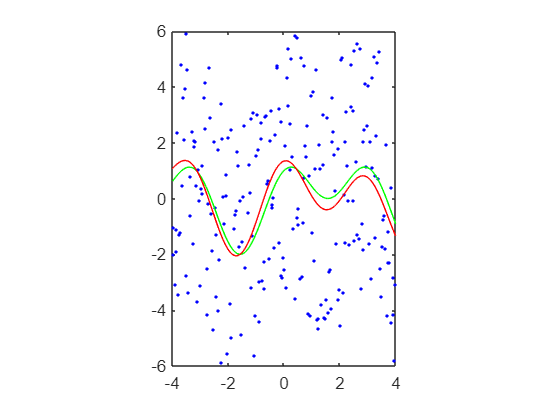

A = [xs.^0 xs.^1 xs.^2 sin(xs) cos(xs) sin(2*xs) cos(2*xs)];
xhat = (A'*A)^-1*A'*ys;
yhat  = A*xhat;
fig3 = figure(3);
plot(xs, ys, '.b')
hold on;
plot(xs, f(xs), '-g');
plot(xs, yhat, "-r");
axis([xmin + 1 xmax - 1 ymin ymax]);
daspect([1 1 1]);
hold off